# Self-organizing coordinated task allocation method for sea-air unmanned systems in offshore wind power environment

clc
clear
close

## Environmental statement and general description

### 1. 建一个风场

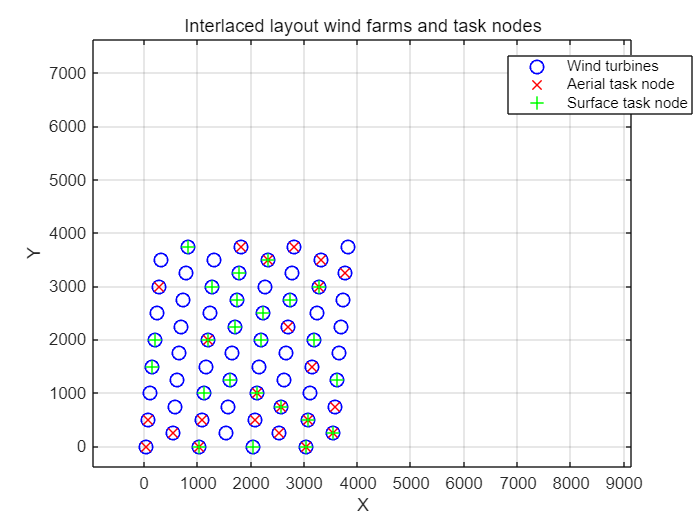

%% 随机化任务集合

% 定义点阵的行数和列数
numRows = 8; % 行数
numCols = 8; % 列数（每组两列）
groupSpacing = 0; % 每组之间的额外距离

% 定义点之间的间距
spacing = 500;

% 初始化点集
points = zeros(numRows * numCols, 2);

% 生成交错点阵，每组两列之间增加距离
index = 1;
for i = 1:numRows
    for j = 1:numCols
        % 每相邻的两列的点在行上交错排列
        if mod(j, 2) == 0
            y = (i - 1) * spacing + spacing / 2; % 偶数列，行上偏移半个间距
        else
            y = (i - 1) * spacing; % 奇数列，不偏移
        end
        % 每组两列之间增加距离
        groupOffset = floor((j - 1) / 2) * groupSpacing;
        x = (j - 1) * spacing + groupOffset + i*40;
        points(index, :) = [x, y];
        index = index + 1;
    end
end

% 随机抽样出两个点集，允许重复
numSamplesAir = 25; % 每个点集的样本数量
numSamplesSur = 30; % 每个点集的样本数量

rng('shuffle'); % 初始化随机数生成器
sampleIndicesAir = randi(size(points, 1), numSamplesAir, 1);
sampleIndicesSur = randi(size(points, 1), numSamplesSur, 1);

sampleSetAir = points(sampleIndicesAir, :);
sampleSetSur = points(sampleIndicesSur, :);

% 绘制原始点阵和抽样点集
figure;
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Wind turbines','MarkerSize',8,'LineWidth',1);
hold on;
plot(sampleSetAir(:, 1), sampleSetAir(:, 2), 'rx', 'DisplayName', 'Aerial task node','MarkerEdgeColor','r','MarkerSize',8,'LineWidth',1);
plot(sampleSetSur(:, 1), sampleSetSur(:, 2), 'g+', 'DisplayName', 'Surface task node','MarkerEdgeColor','g','MarkerSize',8,'LineWidth',1);
hold off;
axis equal;
title('Interlaced layout wind farms and task nodes');
xlabel('X');
ylabel('Y');
legend;
grid on;
xlim([-964 9147])
ylim([-394 7637])
legend(["Wind turbines", "Aerial task node", "Surface task node"], "Position", [0.7250 0.7827 0.2643, 0.1119])

### 2. Air点集组合

% 为每个点生成随机代价
numPoints = size(sampleSetAir, 1);
costs = 800*ones(numPoints, 1);

% 初始化边权重矩阵
weightMatrix = inf*ones(numPoints, numPoints);

% 计算Air边权重矩阵
for i = 1:numPoints
    for j = i+1:numPoints
        % 计算欧几里得距离
        distance = norm(sampleSetAir(i, :) - sampleSetAir(j, :));
        % 计算两个点的代价平均数
        avgCost = (costs(i) + costs(j)) / 2;
        % 计算边的权重
        weight = distance + avgCost;
        % 填充权重矩阵
        weightMatrix(i, j) = weight;
        weightMatrix(j, i) = weight;
    end
end

% 初始化边权重矩阵
distanceMatrix = inf*ones(numPoints, numPoints);

% 计算Air边权重矩阵
for i = 1:numPoints
    for j = i+1:numPoints
        % 计算欧几里得距离
        distance = norm(sampleSetAir(i, :) - sampleSetAir(j, :));
        % 计算边的权重
        weight = distance;
        % 填充权重矩阵
        distanceMatrix(i, j) = weight;
        distanceMatrix(j, i) = weight;
    end
end
distanceMatrix=distanceMatrix;

### 初始化组

remainingPoints = 1:numPoints;
groups = {};
groups_cost = {};
remainingCosts = costs;

% 遍历寻组
while sum(remainingPoints) ~= 0 

    % 找到最短的一个任务点
    [nowCost,nowIdx] = min(remainingCosts);

    % 本组的现有点和总代价
    bestGroup = nowIdx;
    bestCost  = nowCost;
    
    % 去掉这个点
    remainingPoints(nowIdx) = 0;
    remainingCosts(nowIdx) = inf;
    distanceMatrix(:,nowIdx) = inf;
    
    TempSumCost = nowCost;

    % 对剩下点的距离排序
    Weilist = distanceMatrix(bestGroup,:);
    [Weilist,lists] = sort(Weilist);

    i=1;
    % 开始以这个点为基础，找到不超过T的最大
    while 1
        nextIdx = lists(i);
        short = findshortestDis(nextIdx, bestGroup, distanceMatrix);
        TempSumCost = TempSumCost + short + costs(nextIdx);
        if TempSumCost >= 3000 
            break
        end
        distanceMatrix(:,nextIdx) = inf;
        remainingPoints(nextIdx) = 0;
        remainingCosts(nextIdx) = inf; 
        bestGroup = [bestGroup, nextIdx];
        bestCost  = TempSumCost;
        i=i+1;
    end
    groups{end+1} = bestGroup; 
    groups_cost{end+1} = bestCost;
end


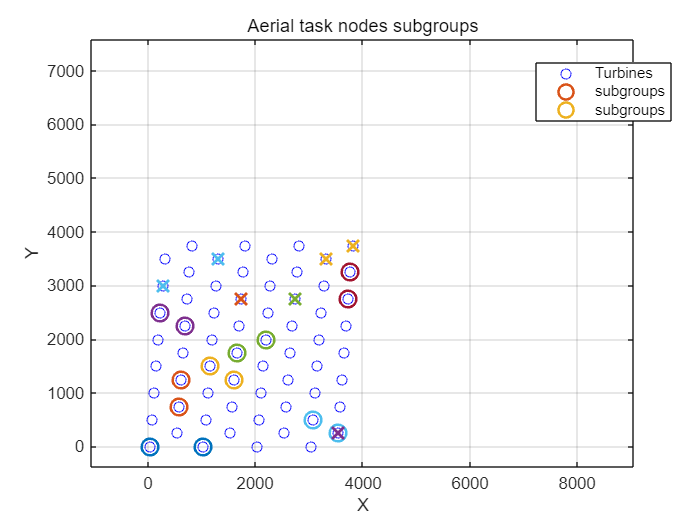

close 
figure;
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Turbines');
hold on;
for i=1:7
    AA=cell2mat(groups(i));
    plot(sampleSetAir(AA, 1), sampleSetAir(AA, 2),'o','MarkerSize',10,'LineWidth',1.5);
end

for i=8:length(groups)
    AA=cell2mat(groups(i));
    plot(sampleSetAir(AA, 1), sampleSetAir(AA, 2),'x','MarkerSize',10,'LineWidth',1.5);
end

hold off;
axis equal;
title('Aerial task nodes subgroups');
xlabel('X');
ylabel('Y');
legend('Turbines','subgroups');
grid on;

xlim([-1060 9052])
ylim([-385 7590])
legend(["Turbines", "subgroups", "subgroups"], "Position", [0.7664 0.7694 0.1929, 0.1119])

### 3. 计算每个组内的重心

ga=zeros(size(groups,2),2);
cost_ga=zeros(size(groups,2),1);
for i=1:size(groups,2)
    AA=cell2mat(groups(i));
    xx=sum(sampleSetAir(AA,1))/length(AA);
    yy=sum(sampleSetAir(AA,2))/length(AA);
    ga(i,:) = [xx, yy];
    cost_ga(i) = cell2mat(groups_cost(i));
end

%% 重组海面任务集合
Expand_node = [sampleSetSur;ga];
costs_sur = 800*ones(numSamplesSur, 1);
Expand_Cost = [costs_sur; cost_ga];

%% 谱聚类！
% 初始化边权重矩阵
weightMatrix = zeros(size(Expand_node,1), size(Expand_node,1));

% 计算Air边权重矩阵
for i = 1:numPoints
    for j = i+1:numPoints
        % 计算欧几里得距离
        distance = norm(Expand_node(i, :) - Expand_node(j, :));
        % 计算两个点的代价平均数
        avgCost = (Expand_Cost(i) + Expand_Cost(j)) / 2;
        % 计算边的权重
        weight = distance + avgCost;
        % 填充权重矩阵
        weightMatrix(i, j) = weight;
        weightMatrix(j, i) = weight;
    end
end


for j=1:length(Expand_Cost)
    AcAA(j)=sum(weightMatrix(j,:))/length(Expand_Cost);
end


dataSet = [Expand_node];
numPoints=size(dataSet,1);
num_clusters=5;
Sigma=1;

idx = kmeans(dataSet,num_clusters);
%idx = spectralcluster(weightMatrix,num_clusters,'Distance','precomputed');


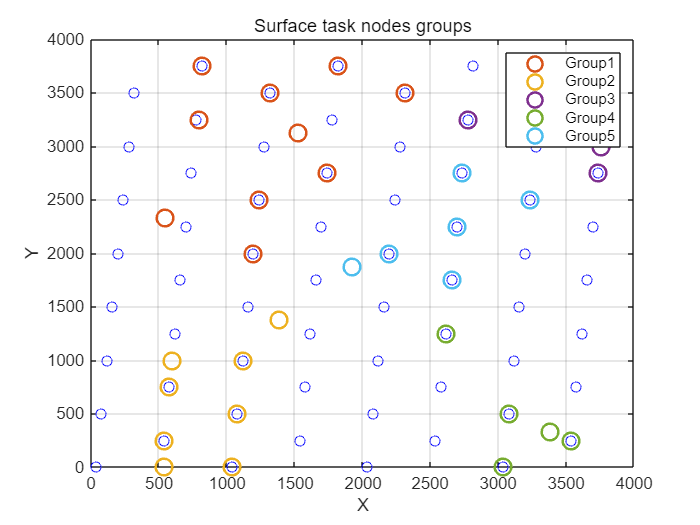

figure(3)
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Turbines');
hold on;
for i=1:num_clusters
    plot(dataSet(idx==i,1),dataSet(idx==i,2),'o','MarkerSize',10,'LineWidth',1.5)
end
hold off
legend('','Group1','Group2','Group3','Group4','Group5')
%axis equal;
title('Surface task nodes groups');
xlabel('X');
ylabel('Y');
grid on;

for i=1:num_clusters
    CC(i)=sum(Expand_Cost(idx==i));
end

## 4. SOM路径任务调度

## Global multi-layer task allocation framework

## Local cooperative task allocation

clc
clear

### 1. 独立航空点任务 - 1点

AirSet = [500, 0];
Airs = [AirSet(1,1),AirSet(1,2)];
Aire = [AirSet(end,1),AirSet(end,2)];
range = 100;

SurSet = [0, -100; 1000, -100];
us = 2;
ua = 15;
CostA = [800];

% X = [x_1,y_1,x_2,y_2,u];
fobj = @(x) sinoAirObjfuntion(x, AirSet, SurSet, us, CostA);

lb=[Airs(1)-range,Airs(2)-range,Aire(1)-range,Aire(2)-range,1,10];              
ub=[Airs(1)+range,Airs(2)+range,Aire(1)-range,Aire(2)-range,3,20]; 

SearchAgents_no=100; 
Max_iteration=300; 
dim=6; 
[Best_pos,Best_score,SAO_curve]=GDSAO(SearchAgents_no,Max_iteration,lb,ub,dim,fobj); 

%Best_pos
[objf,F1,F2] = costfun(Best_pos, AirSet, SurSet, us, CostA)

objf = 512.4688

F1 = 0

F2 = -801.2420

## 复合航空点任务 - 1点

AirSet = [250, 500; 500, 0; 750, 500];
Airs = [AirSet(1,1),AirSet(1,2)];
SurSet = [0, -100; 500, 0; 1000, -100];
range = 200;
us = 2;
ua = 15;
CostA = [500; 1000 ; 500];
CostS = [1000];

% X = [x_1,y_1,u_s,v_a];
fobj = @(x) CompleObjfuntionD(x, AirSet, SurSet, us, CostA, CostS);

lb=[Airs(1)-range,Airs(2)-range,1,10];              
ub=[Airs(1)+range,Airs(2)+range,3,20]; 

SearchAgents_no=100; 
Max_iteration=300; 
dim=4; 
[Best_pos,Best_score,SAO_curve]=GDSAO(SearchAgents_no,Max_iteration,lb,ub,dim,fobj); 

%Best_pos
[G] = findG(Best_pos, AirSet, SurSet, us, CostA, CostS)

G =         1000        -100
